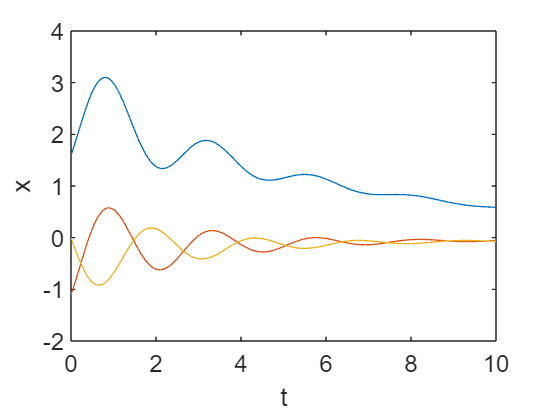

% Clear previous variables and close any open figures
clc; clear; close all;

% 1. Define the ODE as an anonymous function.
% x''' = -x - 7 x' - x''
% two inputs: t, y = [x, x', x''] for ode45.
f = @(t, y) [y(2), y(3), -y(1)-7*y(2)-y(3)]';

% 2. Time span and initial condition.
tspan = [0 10];               % Time interval
y01 = [1.6,2.3,4.1];         % Initial condition - t=0
y02 = [-1.1,2.3,4.1];        % Initial condition - t=0
y03 = [0,-2.3,0.1];          % Initial condition - t=0

% 3. Solve the ODE using ode45 return: t and y values.
[t1, y1] = ode45(f, tspan, y01);
[t2, y2] = ode45(f, tspan, y02);
[t3, y3] = ode45(f, tspan, y03);

% 4. Plot the solutions (functions of t)
% The solutions look like they go to zero (decay) after wiggling a bit
figure, clf % Clears the pile of figures.
plot(t1, y1(:,1));
hold on
plot(t2, y2(:,1));
plot(t3, y3(:,1));
xlabel('t'); ylabel('x');
hold off

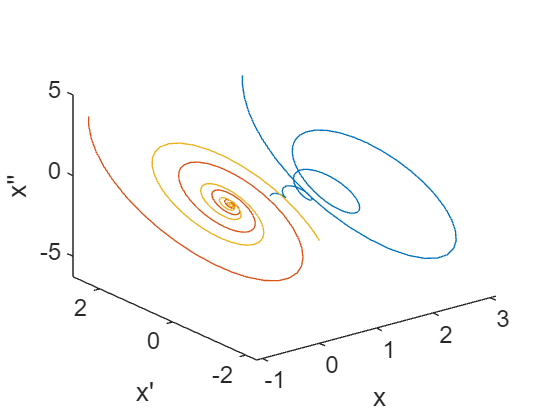


% 5. Phase plot
figure, clf
plot3(y1(:,1), y1(:,2), y1(:,3))
% This looks silly! 
xlabel('x'); ylabel('x'''); zlabel('x''''')
hold on
plot3(y2(:,1), y2(:,2), y2(:,3))
plot3(y3(:,1), y3(:,2), y3(:,3))
hold off


% 6. Roots of m^3+m^2+7m+1=0;
% All roots have negative real parts.  Solutions decay.
% Complex conjugate pair ~e^(-0.4 t) cos(2.6 t + phi)
% Slowest decay is ~e^(-0.15 t)
% evecs match roots. The evec for -0.15 would be perp to spirals!
p=[1,1,7,1]; A=[[0 1 0]; [0 0 1]; [-1 -7 -1]];
roots(p)

ans =   -0.4273 + 2.5871i
  -0.4273 - 2.5871i
  -0.1454 + 0.0000i


eig(A)

ans =   -0.1454 + 0.0000i
  -0.4273 + 2.5871i
  -0.4273 - 2.5871i
